# ***1.Deterministic spectral analysis***

In this section you will experiment with analyzing deterministic signals that consist of the sum of 2

sinusoids, i.e.,

sc(t) = A0 cos(2πf0t) + A1 cos(2πf1t).

# (a)

First write a Matlab function to generate P seconds of sc(t) sampled at a rate of fs Hz. The function should take as inputs A0, A1, f0, f1, P , and fs.

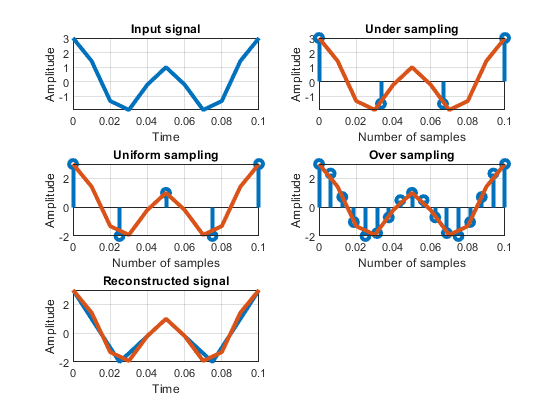

clear all;
close all;
clc;
P=.1;
t=0:0.01:.1;                                             %Time vector
A0=1;                                                    %Amplitude 1
A1=2;                                                    %Amplitude 2
F_0=10;                                                  %Frequency of 1st Sinusoid
F_1=20;                                                  %Frequency of 2nd Sinusoid
Xc= A0*cos(2*pi*F_0*t)+A1*cos(2*pi*F_1*t);               %Input Signal
figure(1)
subplot(3,2,1);plot(t,Xc,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid;
title('Input signal');

fs=1.5*F_1;                                             %Frequency for under sampling
dt_1 = 1/fs;                                            %Samples per second
t_1 = (0:dt_1:P);                                       %Time vector
X_d= A0*cos(2*pi*F_0*t_1)+A1*cos(2*pi*F_1*t_1);
figure(1)
subplot(3,2,2);stem(t_1,X_d,'linewidth',3)
xlabel('Number of samples');ylabel('Amplitude');
hold on;
subplot(3,2,2);plot(t,Xc,'linewidth',3);
grid;
title('Under sampling');

fs2=2*F_1;                                               %Frequency for Uniform sampling
dt_2 = 1/fs2;
t_2 = (0:dt_2:P);
X_d2= A0*cos(2*pi*F_0*t_2)+A1*cos(2*pi*F_1*t_2);
figure(1)
subplot(3,2,3);stem(t_2,X_d2,'linewidth',3);
xlabel('Number of samples');ylabel('Amplitude');
hold on;
subplot(3,2,3);plot(t,Xc,'linewidth',3);
grid;
title('Uniform sampling');

fs3=8*F_1;                                               %Frequency for Over sampling
dt_3 = 1/fs3;
t_3 = (0:dt_3:P);
X_d3= A0*cos(2*pi*F_0*t_3)+A1*cos(2*pi*F_1*t_3);
figure(1)
subplot(3,2,4);stem(t_3,X_d3,'linewidth',3);
hold on;
subplot(3,2,4);plot(t,Xc,'linewidth',3);
xlabel('Number of samples');ylabel('Amplitude');
grid;
title('Over sampling');

n_1= 0:dt_2:P;                                        
Xr= interp1(n_1,X_d2,n_1,'spline');          %Reconstructed signal from uniform sampling
figure(1)
subplot(3,2,5);plot(n_1,Xr,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
hold on
subplot(3,2,5);plot(t,Xc,'linewidth',3);
grid;
title('Reconstructed signal');

***Observations:*** I have taken an input signal which has Amplitude of 1 & 2 and frequency of 10Hz and 20Hz. So, if we want to sample this signal we need take a sample frequency which is 2 times of the maximum frequency of this sinusoids. So, to check this program if it truly works or not, I have taken 3 condition:

- Under Sampling: Fs<Fmax

- Uniform Sampling: Fs= 2*Fmax

- Over sampling: Fs>>2*Fmax

From the plots we can see that, for under sampling frequency we are losing some points of the input signal. For, over sampling, we are getting more points than necessity which need more computation. ANd for uniform sampling, when we reconstruct the whole signal, we got the actual input signal.

In this part, assume the following:

• A0 = A1 = 1

• f0 = 300 Hz

• P = 1 second

• fs = 1500 Hz

**1.When F0=F1**

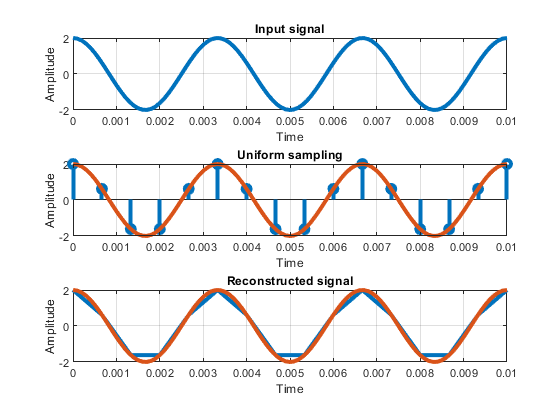

clc
clear var
clear all
P1=.01;
A_0=1;
A_1=1;
F0=300;
Fs_g=1500;
F1=300;
t1=0:0.0001:P1;
Xc1= A_0*cos(2*pi*F0*t1)+A_1*cos(2*pi*F1*t1);
figure(2)
subplot(3,1,1);plot(t1,Xc1,'linewidth',3);
grid on;
xlabel('Time');ylabel('Amplitude');
title('Input signal');

dt_2 = 1/Fs_g;
t_2 = (0:dt_2:P1);
X_d2= A_0*cos(2*pi*F0*t_2)+A_1*cos(2*pi*F1*t_2);
figure(2)
subplot(3,1,2);stem(t_2,X_d2,'linewidth',3);
xlabel('Number of samples');ylabel('Amplitude');
hold on;
subplot(3,1,2);plot(t1,Xc1,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid on;
title('Uniform sampling');

n_1= 0:dt_2:P1;
%%t_1=linspace(0, max(n_1), (max(n_1)/dt))
Xr= interp1(n_1,X_d2,n_1,'spline');
figure(2)
subplot(3,1,3);plot(n_1,Xr,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
hold on
subplot(3,1,3);plot(t1,Xc1,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid on;
title('Reconstructed signal');

**2.When F1=Fs/2**

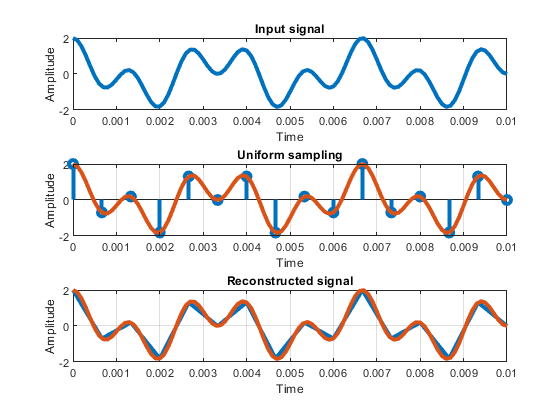

clc
clear var
clear all
P1=.01;
A_0=1;
A_1=1;
F0=300;
Fs_g=1500;
F1=750;
t1=0:0.0001:P1;
Xc1= A_0*cos(2*pi*F0*t1)+A_1*cos(2*pi*F1*t1);
figure(3)
subplot(3,1,1);plot(t1,Xc1,'linewidth',3);
grid;
xlabel('Time');ylabel('Amplitude');
grid;
title('Input signal');

dt_2 = 1/Fs_g;
t_2 = (0:dt_2:P1);
X_d2= A_0*cos(2*pi*F0*t_2)+A_1*cos(2*pi*F1*t_2);
figure(3)
subplot(3,1,2);stem(t_2,X_d2,'linewidth',3);
xlabel('Number of samples');ylabel('Amplitude');
hold on;
subplot(3,1,2);plot(t1,Xc1,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid;
title('Uniform sampling');

n_1= 0:dt_2:P1;
%%t_1=linspace(0, max(n_1), (max(n_1)/dt))
Xr= interp1(n_1,X_d2,n_1,'spline');
figure(3)
subplot(3,1,3);plot(n_1,Xr,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
hold on
subplot(3,1,3);plot(t1,Xc1,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid;
title('Reconstructed signal');

**3.When F1>Fs**

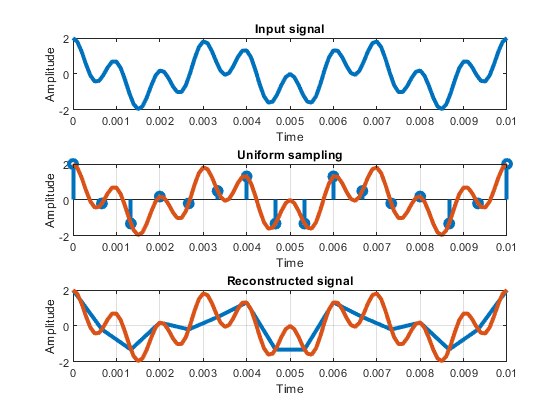

clc
clear var
clear all
P1=.01;
A_0=1;
A_1=1;
F0=300;
Fs_g=1500;
F1=1000;
t1=0:0.0001:P1;
Xc1= A_0*cos(2*pi*F0*t1)+A_1*cos(2*pi*F1*t1);
figure(4)
subplot(3,1,1);plot(t1,Xc1,'linewidth',3);
grid;
xlabel('Time');ylabel('Amplitude');
grid;
title('Input signal');

dt_2 = 1/Fs_g;
t_2 = (0:dt_2:P1);
X_d2= A_0*cos(2*pi*F0*t_2)+A_1*cos(2*pi*F1*t_2);
figure(4)
subplot(3,1,2);stem(t_2,X_d2,'linewidth',3);
xlabel('Number of samples');ylabel('Amplitude');
hold on;
subplot(3,1,2);plot(t1,Xc1,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid;
title('Uniform sampling');

n_1= 0:dt_2:P1;
%%t_1=linspace(0, max(n_1), (max(n_1)/dt))
Xr= interp1(n_1,X_d2,n_1,'spline');
figure(4)
subplot(3,1,3);plot(n_1,Xr,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
hold on
subplot(3,1,3);plot(t1,Xc1,'linewidth',3);
xlabel('Time');ylabel('Amplitude');
grid;
title('Reconstructed signal');

***Observations:***  

1. When F1=F0, we can see, the reconstructed signal has minor missing points.

2. When F1=Fs/2, we can see, the reconstructed signal has no missing points. Reconstructed signal has same property of input signal.

3. When F1>Fs, we can see, the reconstructed signal is completly different than the input signal.

So, it would be better if we take F1 closer to F0. Such as F1=Fs/2.

## `Hanning Window`

fs=1500;
winLength = 45;                                                   %Length of hanning window
w = hann(winLength);                                            %Function of hanning window

t_l = 0:(1/Fs_g):999;                             %Sample points for whole duration-999 sec
output = A_0*cos(2*pi*F0*t_l)+A_1*cos(2*pi*F1*t_l);        %Sinusoids wave of long duration
figure(5)
subplot(3,1,1)
plot(t_l(1:100),output(1:100),'linewidth',3)    %Plotting the first 100 samples of Sinusoids
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('Before Hanning Windowing')

figure(5)
subplot(3,1,2)
stem(w,'linewidth',3)                                             %Plotting Window function
grid on
xlabel('n')
ylabel('w(n)')
title('Hanning Window')

index = 34;                                                   %Starting index for windowing
winSequence = [zeros(1,index-1) w' zeros(1,length(output)-index-length(w)+1)]; 
                                          %Windowing Sequence of same duration as Sinusoids
winOut = output.*winSequence;
                                                 %Product of sequences to perform windowing 
figure(5)
subplot(3,1,3)
n=length(winOut)

n = 1498501

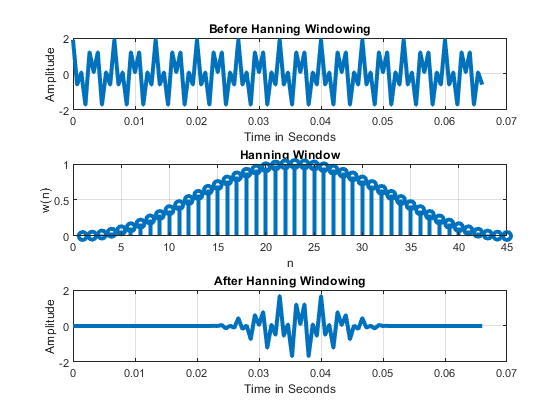

%winOut=fft(winOut)
%fshift = (-n/2:n/2-1)*(fs/n);
plot(t_l(1:100),winOut(1:100),'linewidth',3)%First 100 samples of Resulting plot of windowing
%plot(fshift,winOut)
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('After Hanning Windowing')

## `Rectangular Window`

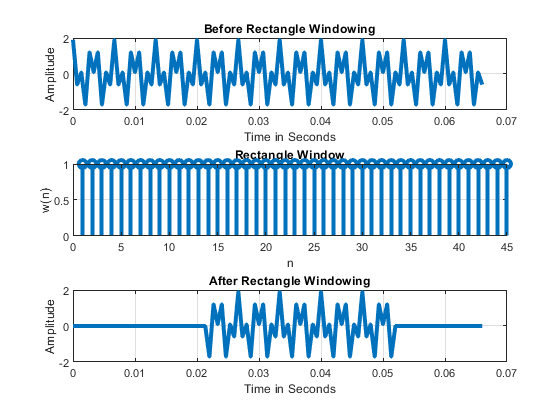

winLength = 45;                                                 %Length-Rectangular window
w = rectwin(winLength);                                    %Function of Rectangular window

t_l = 0:(1/Fs_g):999;                            %Sample points for whole duration-999 sec

output = A_0*cos(2*pi*F0*t_l)+A_1*cos(2*pi*F1*t_l);       %Sinusoids wave of long duration

figure(6)
subplot(3,1,1)
plot(t_l(1:100),output(1:100),'linewidth',3)  %Plotting the first 100 samples of Sinusoids
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('Before Rectangle Windowing')

figure(6)
subplot(3,1,2)
stem(w,'linewidth',3)                                            %Plotting Window function
grid on
xlabel('n')
ylabel('w(n)')
title('Rectangle Window')

index = 34;                                                  %Starting index for windowing
winSequence = [zeros(1,index-1) w' zeros(1,length(output)-index-length(w)+1)]; 
                                         %Windowing Sequence of same duration as Sinusoids
winOut = output.*winSequence;                %Product of sequences to perform windowing
 
figure(6)
subplot(3,1,3)
plot(t_l(1:100),winOut(1:100),'linewidth',3)%First 100 samples of Resulting plot of windowing
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('After Rectangle Windowing')

***Observations:***  

- After applying Hanning window we got a signal which has been filtered throught the window. It has been chopped of from certain portion in time domain.

- After applying Rectangular window we also got filtered by the windwing. But this time the signal has more range than the hanning window.

## ***Hanning Window***

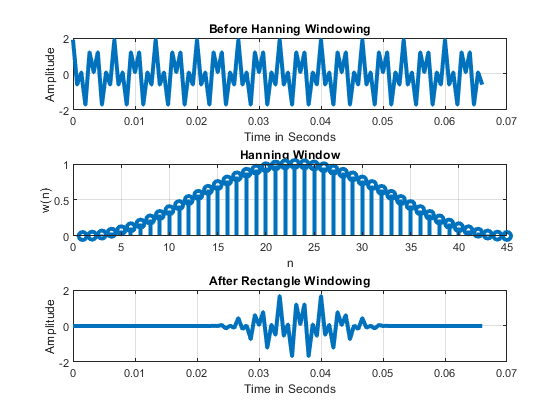

A_0=1;
A_1=.9;
F0=300;
Fs_g=1500;
F1=1500/2;

winLength = 45;                                        %Length of hanning window
w = hann(winLength);                                 %Function of hanning window

t_l = 0:(1/Fs_g):999;                     %Sample points for whole duration-999 sec

output = A_0*cos(2*pi*F0*t_l)+A_1*cos(2*pi*F1*t_l);%Sinusoids wave of long duration

figure(7)
subplot(3,1,1)
plot(t_l(1:100),output(1:100),'linewidth',3)%Plotting the first 100 samples of Sinusoids
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('Before Hanning Windowing')

figure(7)
subplot(3,1,2)
stem(w,'linewidth',3)                                      %Plotting Window function
grid on
xlabel('n')
ylabel('w(n)')
title('Hanning Window')

index = 34;                                            %Starting index for windowing
winSequence = [zeros(1,index-1) w' zeros(1,length(output)-index-length(w)+1)]; 
                                   %Windowing Sequence of same duration as Sinusoids
winOut = output.*winSequence;          %Product of sequences to perform windowing
 
figure(7)
subplot(3,1,3)
plot(t_l(1:100),winOut(1:100),'linewidth',3)%First 100 samples of Resulting plot of windowing
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('After Rectangle Windowing')

## ***Rectangular Window***

winLength = 45;                                         %Length-Rectangular window
w = rectwin(winLength);                            %Function of Rectangular window

t_l = 0:(1/Fs_g):999;                       %Sample points for whole duration-999 sec

output = A_0*cos(2*pi*F0*t_l)+A_1*cos(2*pi*F1*t_l);  %Sinusoids wave of long duration

figure(8)
subplot(3,1,1)
plot(t_l(1:100),output(1:100),'linewidth',3)%Plotting the first 100 samples of Sinusoids
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('Before Rectangle Windowing')

figure(8)
subplot(3,1,2)
stem(w,'linewidth',3)                                         %Plotting Window function
grid on
xlabel('n')
ylabel('w(n)')
title('Rectangle Window')

index = 34;                                               %Starting index for windowing
winSequence = [zeros(1,index-1) w' zeros(1,length(output)-index-length(w)+1)]; 
                                      %Windowing Sequence of same duration as Sinusoids
winOut = output.*winSequence;             %Product of sequences to perform windowing
 
figure(8)
subplot(3,1,3)
plot(t_l(1:100),winOut(1:100),'linewidth',3)%First 100 samples of Resulting plot of windowing
grid on
xlabel('Time in Seconds')
ylabel('Amplitude')
title('After Rectangle Windowing')

***Answer/Observations:***  

After making A1 smaller than A0, we got the same result in time domain. The signals we got from both of the windows has same components like previous part.